verticesCube = [
    -1 , 1 , 1 , -1 , -1 , 1 , 1 , -1;
    -1 , -1 , 1, 1 , -1 , -1 , 1 , 1;
    -1 , -1 , -1 , -1 , 1 , 1 , 1 , 1;
     1 , 1 , 1, 1 , 1 , 1 , 1 , 1
     ]

verticesCube =     -1     1     1    -1    -1     1     1    -1
    -1    -1     1     1    -1    -1     1     1
    -1    -1    -1    -1     1     1     1     1
     1     1     1     1     1     1     1     1



facesCube = [
    1 , 2 , 6, 5;
    2 , 3 , 7, 6;
    3 , 4 , 8, 7;
    4 , 1 , 5, 8;
    1 , 2 , 3, 4;
    5 , 6 , 7, 8
    ]

facesCube =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


В данных визуализациях:

- красный - куб в изначальных координатах (оригинал)

- зеленый - преобразованный куб

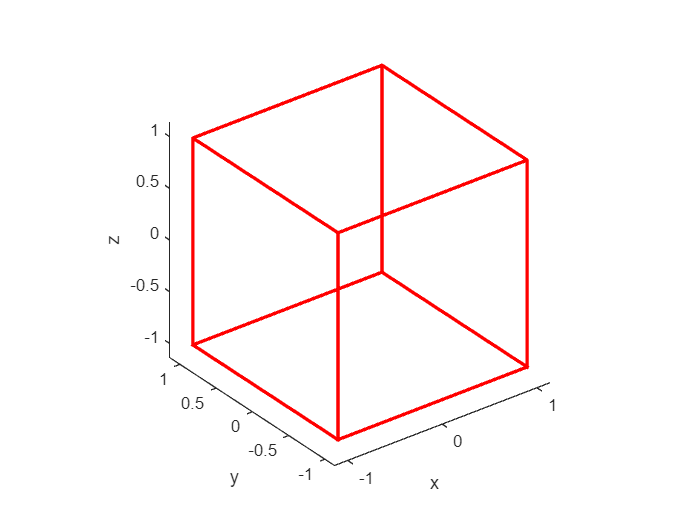

%Задание 1 - оригинал
DrawShape (verticesCube , facesCube , 'red','none');
view (3) ;
axis equal ;
axis padded ;
xlabel('x');
ylabel('y');
zlabel('z');

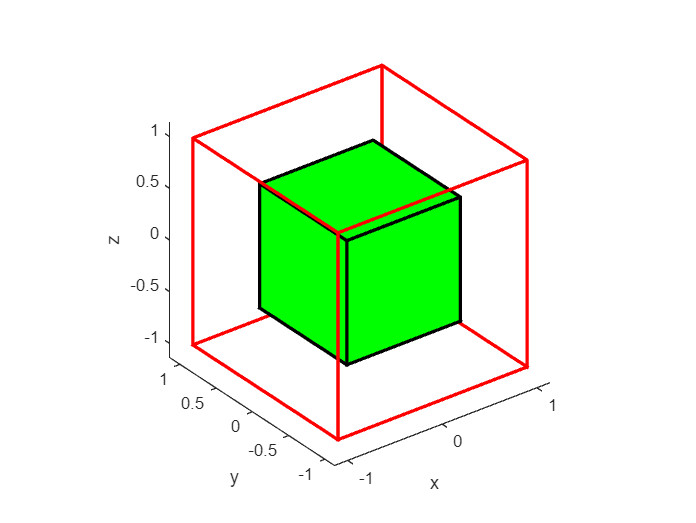

%Задание 2 - масштабирование

%Выбор масштаба:
a=0.6;
A = [
    a 0 0 0;
    0 a 0 0;
    0 0 a 0;
    0 0 0 1
     ];
DrawShape (A*verticesCube, facesCube,'black','g');
view (3) ;
axis equal ;
axis padded ;

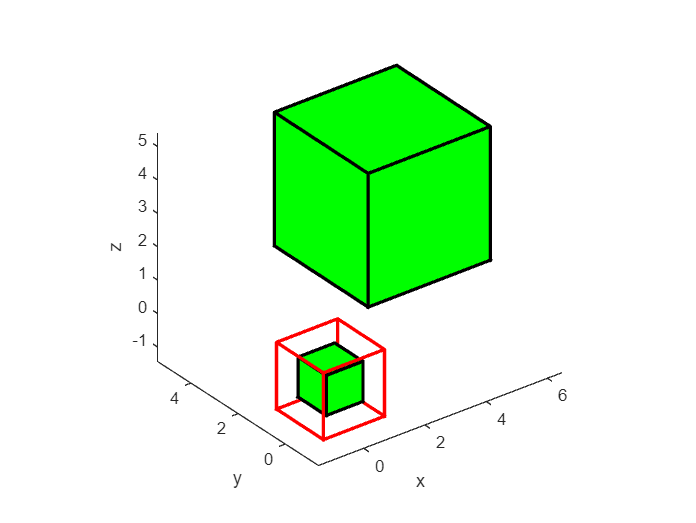

%Задание 3 - масштабирование и перенос

%Выбор масштаба:
a =  2;
%Выбор переноса по 3м осям соответственно: 
b = 4;
c = 3;
d = 3;
A = [
    a 0 0 b;
    0 a 0 c;
    0 0 a d;
    0 0 0 1
     ];
DrawShape (A*verticesCube, facesCube,'black','g');
view (3) ;
axis equal ;
axis padded ;

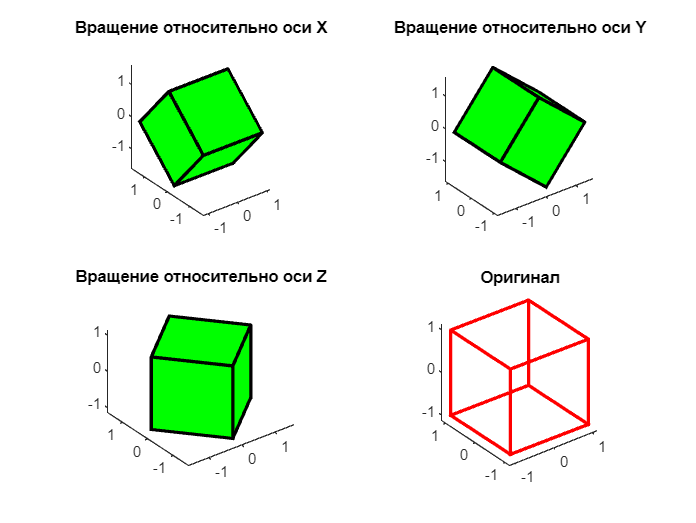

%Задание 4 - вращение

%Выбора угла поворота по осям X, Y, Z соответственно:
a =0.7;
b =0.7;
c =0.7;
A = [
    1 0 0 0;
    0 cos(a) -sin(a) 0;
    0 sin(a) cos(a) 0;
    0 0 0 1
     ];
B = [
    cos(b) 0 sin(b) 0;
    0 1 0 0;
    -sin(b) 0 cos(b) 0;
    0 0 0 1
     ];
C = [
    cos(c) -sin(c) 0 0;
    sin(c) cos(c) 0 0;
    0 0 1 0;
    0 0 0 1
     ];

tiledlayout(2,2);
nexttile
DrawShape (A*verticesCube, facesCube,'black','g');
view(3);
axis equal ;
axis padded ;
title('Вращение относительно оси X');
nexttile
DrawShape (B*verticesCube, facesCube,'black','g');
view(3);
axis equal ;
axis padded ;
title('Вращение относительно оси Y');
nexttile;
DrawShape (C*verticesCube, facesCube,'black','g');
view (3) ;
axis equal ;
axis padded ;
title('Вращение относительно оси Z');
nexttile;
DrawShape (verticesCube , facesCube , 'red','none');
view (3) ;
axis equal ;
axis padded ;
title('Оригинал');

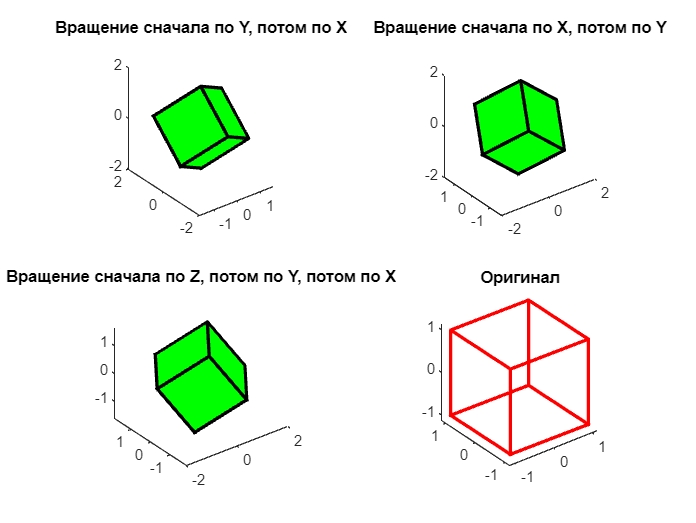

%Задание 4_1 - сложное вращение
tiledlayout(2,2);
nexttile;
DrawShape (A*B*verticesCube, facesCube,'black','g');
view (3) ;
axis equal ;
axis padded ;
title('Вращение сначала по Y, потом по X');
nexttile;
DrawShape (B*A*verticesCube, facesCube,'black','g');
view (3) ;
axis equal ;
axis padded ;
title('Вращение сначала по X, потом по Y');
nexttile;
DrawShape (A*B*C*verticesCube, facesCube,'black','g');
view (3) ;
axis equal ;
axis padded ;
title('Вращение сначала по Z, потом по Y, потом по X');
nexttile;
DrawShape (verticesCube , facesCube , 'red','none');
view (3) ;
axis equal ;
axis padded ;
title('Оригинал');

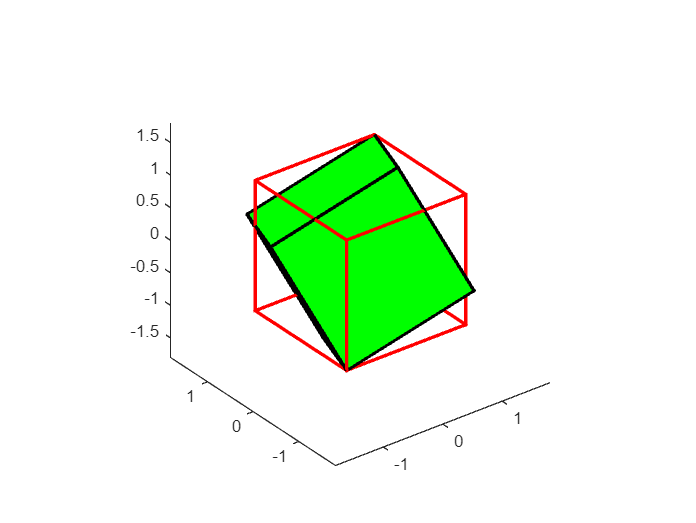

%Задание 5 - вращение вокруг вершины
%Выбор вершины куба для вращения:
x =-1;
y =-1;
z =-1;
%Выбор угла поворота:
thetta =0.7;
abc=sqrt(x^2+y^2+z^2);
A = [
    cos(thetta)+((x/abc)^2)*(1-cos(thetta)) (x/abc)*(y/abc)*(1-cos(thetta))-(z/abc)*sin(thetta) (x/abc)*(z/abc)*(1-cos(thetta))+(y/abc)*sin(thetta) 0;
    (y/abc)*(x/abc)*(1-cos(thetta))+(z/abc)*sin(thetta) cos(thetta)+((y/abc)^2)*(1-cos(thetta)) (y/abc)*(z/abc)*(1-cos(thetta))-(x/abc)*sin(thetta) 0;
    (z/abc)*(x/abc)*(1-cos(thetta))-(y/abc)*sin(thetta) (z/abc)*(y/abc)*(1-cos(thetta))+(x/abc)*sin(thetta) cos(thetta)+((z/abc)^2)*(1-cos(thetta)) 0;
    0 0 0 1;
     ];

tiledlayout(1,1)
nexttile
DrawShape (A*verticesCube, facesCube,'black','green');
view(3);
axis equal ;
axis padded ;
DrawShape (verticesCube , facesCube , 'red','none');
view (3) ;

function DrawShape ( vertices , faces , Edgecolor, Facecolor)
    patch('Vertices', (vertices (1:3 ,:) ./ vertices (4 ,:) )', 'Faces', faces , 'EdgeColor', Edgecolor,'LineWidth',2,'FaceColor', Facecolor);
end